# 交互教学 02：储能分时电价套利与荷电状态

给定额定功率和额定能量容量，求解全天充放电计划。比较有、无充放电互斥约束时的最优电费收益。

## 使用方法

先将 MATLAB 当前文件夹切换到 interactive，再点击“全部运行”。修改容量、效率或模型选项后重新运行；时段滑块只更新图形。

lesson=ess_live_setup();
profiles=load(fullfile(lesson.cases,'profiles_24h.mat'));
T=profiles.T;price_MWh=profiles.price_MWh;price_kWh=profiles.price_kWh;
export_figures=true;
yalmip('clear');

## 给定容量与充放电效率

单节点储能不计配电网潮流约束。本课程按同一时段的给定电价结算充放电电费，初末荷电状态均为 0.50。

P_rated = 2;
E_rated = 2;
eta_ch = 0.9;
eta_dis = 0.95;
use_binary = true;
SoC_0=0.5;SoC_min=0.1;SoC_max=1.0;dt=1;

## 声明决策变量

功率与荷电状态为连续变量；采用互斥约束时，充放电状态为 0-1 变量。

P_ch  = sdpvar(T, 1, 'full'); % 充电功率 P_t^{ch} (MW)
P_dis = sdpvar(T, 1, 'full'); % 放电功率 P_t^{dis} (MW)
SoC   = sdpvar(T, 1, 'full'); % 荷电状态 SoC_t
if use_binary
    u_ch=binvar(T,1,'full');
else
    u_ch=sdpvar(T,1,'full');
end % 充电状态二进制变量 u_t^{ch} \in {0,1}

## 构造功率与荷电状态约束

先设置功率上限，再按所选模型决定是否加入充放电互斥约束。


$$\mathrm{SoC}_t=\mathrm{SoC}_{t-1}+(\eta_{\mathrm{ch}}P_t^{\mathrm{ch}}-P_t^{\mathrm{dis}}/\eta_{\mathrm{dis}})\Delta t/E_{\mathrm{rated}}$$


Constraints = [];
Constraints=[Constraints,0<=P_ch<=P_rated,0<=P_dis<=P_rated];
if use_binary
    Constraints=[Constraints,P_ch<=u_ch*P_rated,P_dis<=(1-u_ch)*P_rated];
end
Constraints = [Constraints, SoC_min <= SoC <= SoC_max];
Constraints = [Constraints, SoC(T) == SoC_0];
for t = 1:T
    if t == 1
        soc_prev = SoC_0;
    else
        soc_prev = SoC(t - 1);
    end
    Constraints = [Constraints, SoC(t) == soc_prev + ...
        (eta_ch * P_ch(t) * dt) / E_rated - (P_dis(t) * dt) / (eta_dis * E_rated)];
end

## 设置电费收益并求解

YALMIP 求解最小化问题，因此将日套利收益取负号。


$$R=\sum_t c_t(P_t^{\mathrm{dis}}-P_t^{\mathrm{ch}})\Delta t$$


Total_Revenue = sum(price_MWh .* (P_dis - P_ch) * dt);
Objective     = -Total_Revenue;
if use_binary,problem_class='MILP';else,problem_class='LP';end
[sol,solver_name,solve_seconds]=ess_live_solve(Constraints,Objective,problem_class);
disp(table(string(solver_name),value(Total_Revenue),'VariableNames',{'Solver','DailyRevenue_Yuan'}));

       Solver       DailyRevenue_Yuan
    ____________    _________________

    "intlinprog"         1553.6      



## 交互查看充放电与荷电状态

滑块选择时段，在功率、电价与荷电状态曲线上查看同一时段。净放电功率为放电功率减充电功率，放电为正、充电为负。

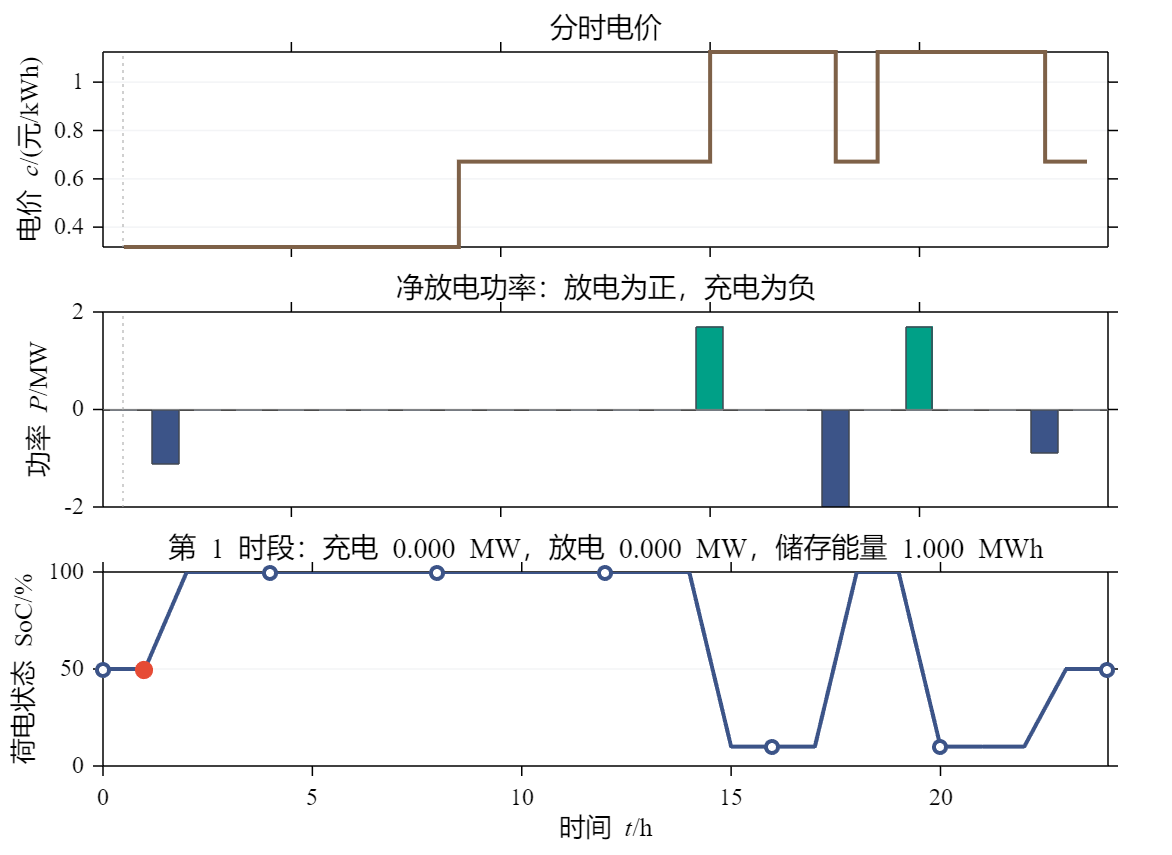

view_hour = 1;
P_ch_value=value(P_ch);P_dis_value=value(P_dis);SoC_value=value(SoC);
fig_arbitrage=ess_live_view('arbitrage',price_kWh,P_ch_value,P_dis_value,SoC_value,view_hour,dt,E_rated);

## 相同参数下比较 LP 与 MILP

比较最优收益、同时充放电功率和末态荷电状态误差。电价相同的多个时段可能对应不同的最优运行安排。

Comparison=ess_live_compare_arbitrage(price_MWh,P_rated,E_rated,eta_ch,eta_dis,SoC_min,SoC_max,dt);
disp(Comparison);

    Model     DailyRevenue_Yuan    MaxSimultaneousPower_MW    TerminalSoCError
    ______    _________________    _______________________    ________________

    "LP"           1553.6                     0                      0        
    "MILP"         1553.6                     0                      0        



## 保存结果与练习

分别改变额定功率和额定能量容量，观察受约束的充放电时段。解释功率上限与可用电量对收益的不同影响。

out_dir=fullfile(lesson.results,'Lesson02');
if export_figures,ess_live_export(fig_arbitrage,out_dir,'Arbitrage_Explorer');end

Lesson_Stats=struct('Lesson',2,'Revenue_Yuan',value(Total_Revenue),'LP_MILP_Difference',abs(diff(Comparison.DailyRevenue_Yuan)));